rng default
samples = 100000

samples = 100000

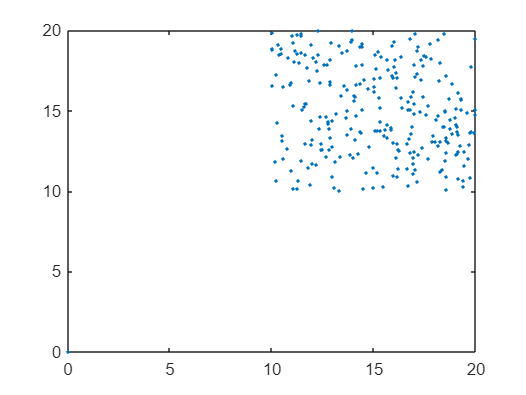

xq = sizes.* rand(samples,1)+10;
yq = sizes.* rand(samples,1)+10;
%%[in,on] = inpolygon(xq,yq,bots(1).verts(1,:),bots(1).verts(2,:));
quad_vertex = [10 10; 10 20; 20 20; 20 10];
[in,on] = inpolygon(xq,yq,quad_vertex(:,1),quad_vertex(:,2));
plot(in.*xq,in.*yq,'.');

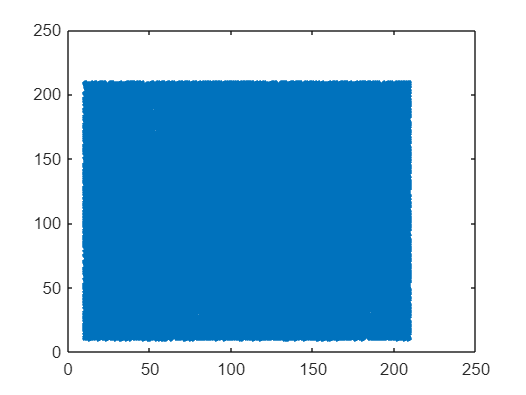

plot(xq,yq,'.');

area=(numel(xq(in))+numel(xq(on)))/samples*sizes^2

area = 106.8000

xc = (sizes^2/area/samples)*(sum(xq(in)+sum(xq(on))))

xc = 15.1577

yc = ((sizes^2/area)/samples)*sum(yq(in)+sum(yq(on)))

yc = 15.0034

[x,y]=centroid(polyshape(quad_vertex))

x = 15

y = 15

polyg = polyshape(bots(1).verts(1,:),bots(1).verts(2,:))

polyg =   polyshape with properties:

      Vertices: [31×2 double]
    NumRegions: 1
      NumHoles: 0


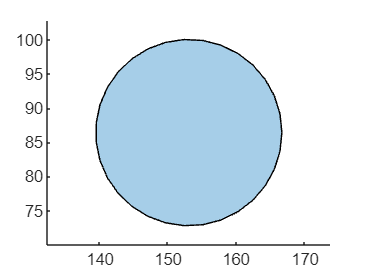

plot(polyg)
axis equal

xx=[0;0]

xx =      0
     0


clear area
area(polyg)

ans = 580.1889

[a,b]=centroid(polyg)

a = 153.0501

b = 86.4054

MC_int_2D(20,bots(1).pos,bots(1).verts)

ans =   399.0000  153.0666   86.3225



rng default
samples = 10000

samples = 10000

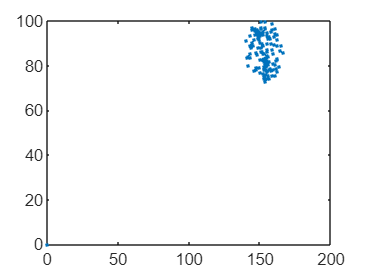

xq = sizes.* rand(samples,1)+a-sizes/2;
yq = sizes.* rand(samples,1)+b-sizes/2;
[in,on] = inpolygon(xq,yq,bots(1).verts(1,:),bots(1).verts(2,:));
plot(in.*xq,in.*yq,'.');

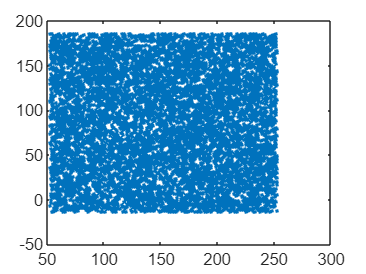

plot(xq,yq,'.');

area=(numel(xq(in))+numel(xq(on)))/samples*sizes^2

area = 508

xc = ((sizes^2/area)/samples)*(sum(xq(in)+sum(xq(on))))

xc = 153.2465

yc = ((sizes^2/area)/samples)*sum(yq(in)+sum(yq(on)))

yc = 86.6204

mu = [0 0];
Sigma = [0.25 0.3; 0.3 1];
x1 = -3:0.2:3;
x2 = -3:0.2:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];
y = mvnpdf(X,mu,Sigma);
y = reshape(y,length(x2),length(x1))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0010    0.0020    0.0033    0.0043    0.0043    0.0033    0.0020    0.0010    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0030    0.0053    0.0073    0.0079    0.0066    0.0043    0.0022    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005    0.0017    0.0041    0.0078    0.0116    0.0135    0.0122    0.0086    0.0047    0.0020    0.0007    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   

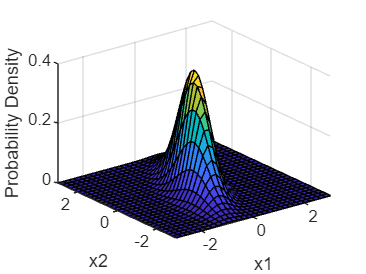

surf(x1,x2,y)
axis([-3 3 -3 3 0 0.4])
xlabel('x1')
ylabel('x2')
zlabel('Probability Density')

a=random_rect(50)

a =    10.9739   11.0739   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232
   19.4045   19.4045   19.4045   19.5045   19.6045   19.7045   19.8045   19.9045   20.0045   20.1045   20.2045   20.3045   20.4045   20.5045   20.6045   20.7045   20.8045   20.9045   21.0045   21.1045   21.2045   21.3045   21.4045   21.5045   21.6045   21.7045   21.8045   21.9045   22.0045   22.1045   22.2045   22.3045   22.4045   22.5045   22.6045   22.7045   22.8045   22.9045   23.0045   23.1045   23.2045   23.3045   23.4045   23.5045   23.6045   23.7045   23.8045   23.9045   24.0045   24

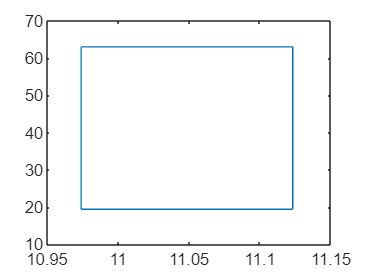


figure
plot(a(1,:),a(2,:))



bots(1).obstacles_in_polar


ans =

     []



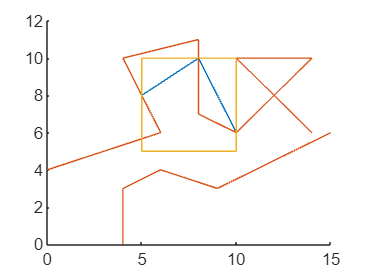

x = [0 6  4  8 8 10 14 10 14 NaN 4 4 6 9 15];
y = [4 6 10 11 7  6 10 10  6 NaN 0 3 4 3  6];
x1 = [5 5 10 10 5];
y1 = [5 10 10 5 5];
[xi,yi] = polyxpoly(x,y,x1,y1);
figure
hold on
plot(xi,yi);
plot(x,y);
plot(x1,y1);

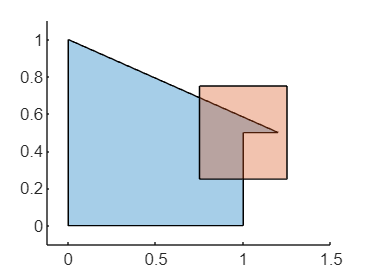

poly1 = polyshape([0 0 1 1 1.2],[1 0 0 0.5 0.5]);
poly2 = polyshape([0.75 1.25 1.25 0.75],[0.25 0.25 0.75 0.75]);
figure
hold on
plot(poly1)
plot(poly2)

polyout = intersect(poly1,poly2)

polyout =   polyshape with properties:

      Vertices: [5×2 double]
    NumRegions: 1
      NumHoles: 0


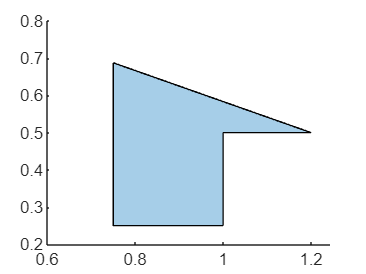

figure
plot(polyout)


%%circle = polyshape(bots(5).pos(1,1)+15.*cos([0:0.1:2*pi]),bots(5).pos(2,1)+15.*sin([0:0.1:2*pi]))
poly1 = polyshape([bots(3).pos(1,1),bots(3).obst(1,:)],[bots(3).pos(2,1),bots(3).obst(2,:)]);

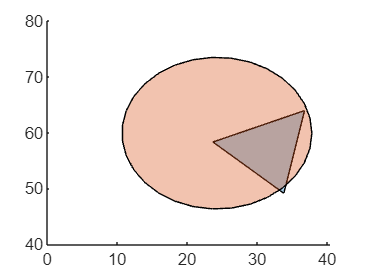

poly2 = polyshape(bots(3).verts_unc(1,:),bots(3).verts_unc(2,:));
figure 
hold on
plot(poly1)
plot(poly2)




a=bots(3).vertex_obst;
poly3 = polyshape(a(1,:),a(2,:));

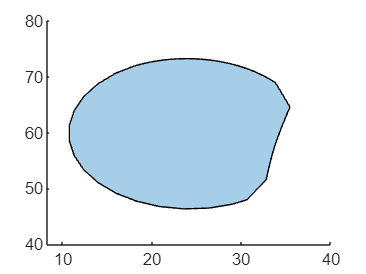

figure
plot(intersect(poly3,poly2));

ob=build_obst([10,20,30,35,20;10,10,20,40,60],100)

ob =    10.0000   10.0100   10.0200   10.0300   10.0400   10.0501   10.0601   10.0701   10.0801   10.0901   10.1001   10.1101   10.1201   10.1301   10.1401   10.1502   10.1602   10.1702   10.1802   10.1902   10.2002   10.2102   10.2202   10.2302   10.2402   10.2503   10.2603   10.2703   10.2803   10.2903   10.3003   10.3103   10.3203   10.3303   10.3403   10.3504   10.3604   10.3704   10.3804   10.3904   10.4004   10.4104   10.4204   10.4304   10.4404   10.4505   10.4605   10.4705   10.4805   10.4905
   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   1

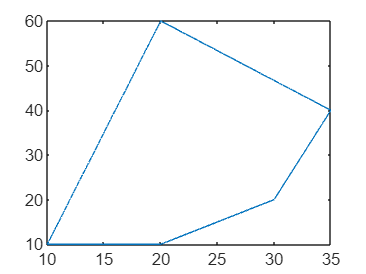


plot(ob(1,:),ob(2,:))

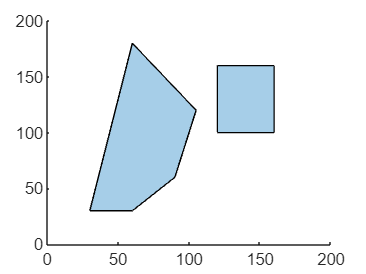



plot(union(poly_obstacles{: ...
    }))

xc=bots(7).pos_est(1,1);
yc=bots(7).pos_est(2,1);
bots(7).steps_vert=40;

%bots(2).steps_vert = 101;

rad = 7

rad = 7

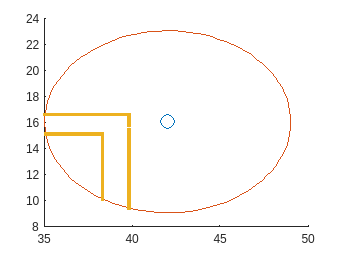

%%bots(2).rs=30/2.2;
update_obstacles(obstacles,bots,n_lidar);
%pp=bots(2).vertex_unc2
[b,a]=lidar_sim(obstacles,[xc;yc],rad,n_lidar);
figure 
hold on
plot(xc,yc,'o',MarkerSize=10)
plot(xc+rad.*cos(linspace(0,2*pi,100)),yc+rad.*sin(linspace(0,2*pi,100)))
plot(xc+b(1,:).*cos(b(2,:)),yc+b(1,:).*sin(b(2,:)),'.')

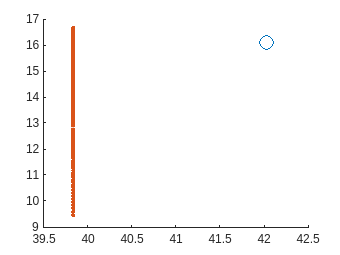


obst = [xc+b(1,:).*cos(b(2,:));yc+b(1,:).*sin(b(2,:))];
obst_inflated =inflate_obsts(a,[xc;yc],0.5) ;  
[~,tmp] = lidar_sim({obst_inflated},[xc;yc],rad,n_lidar);
obst_inflated = polar2cartesian(lidar_sim({obst_inflated},[xc;yc],rad,n_lidar),[xc;yc]);
figure
hold on
plot(xc,yc,'o',MarkerSize=10)
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')

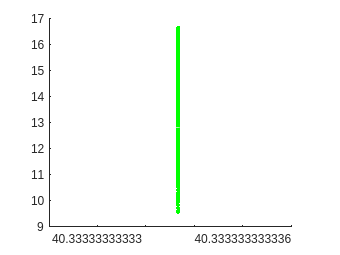


figure
hold on
%plot(xc+b(1,:).*cos(b(2,:)),yc+b(1,:).*sin(b(2,:)),'r.')
plot(obst_inflated(1,:),obst_inflated(2,:),'g.')

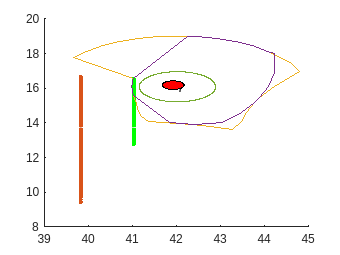

bots(7).vertex_unc2
tmp = cartesian2polar(inflate_obsts(bots(7).obsts_lidar,bots(7).pos(1:2),bots(7).bot_dim + bots(7).uncertainty),bots(7).pos(1:2));
figure
hold on
plot(xc+tmp(1,:).*cos(tmp(2,:)),yc+tmp(1,:).*sin(tmp(2,:)),'g.')
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')
bots(7).plot_bot

id =3;
xc=bots(id).pos(1,1);
yc=bots(id).pos(2,1);

%bots(2).steps_vert = 101;

rad = 4

rad = 4

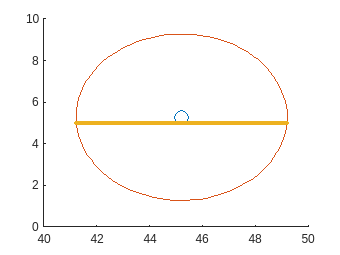

%%bots(2).rs=30/2.2;
%update_obstacles(obstacles,bots,n_lidar);
%pp=bots(2).vertex_unc2
[b,a]=lidar_sim(obstacles,[xc;yc],rad,n_lidar);
figure 
hold on
plot(xc,yc,'o',MarkerSize=10)
plot(xc+rad.*cos(linspace(0,2*pi,100)),yc+rad.*sin(linspace(0,2*pi,100)))
plot(xc+b(1,:).*cos(b(2,:)),yc+b(1,:).*sin(b(2,:)),'.')

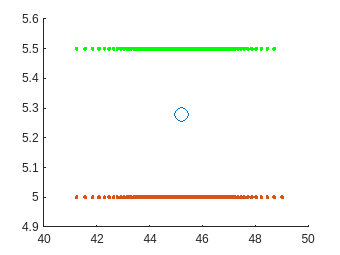


obst = [xc+b(1,:).*cos(b(2,:));yc+b(1,:).*sin(b(2,:))];
obst_inflated =inflate_obsts(a,[xc;yc],0.5) ;  
[~,tmp] = lidar_sim({obst_inflated},[xc;yc],rad,n_lidar);
obst_inflated = polar2cartesian(lidar_sim({obst_inflated},[xc;yc],rad,n_lidar),[xc;yc]);
figure
hold on
plot(xc,yc,'o',MarkerSize=10)
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')
plot(obst_inflated(1,:),obst_inflated(2,:),'g.')

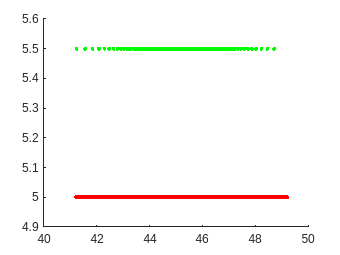

figure
hold on
plot(xc+b(1,:).*cos(b(2,:)),yc+b(1,:).*sin(b(2,:)),'r.')
plot(obst_inflated(1,:),obst_inflated(2,:),'g.')

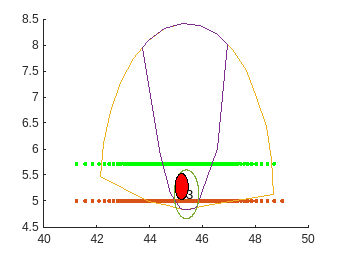

bots(id).vertex_unc2
tmp = cartesian2polar(inflate_obsts(bots(id).obsts_lidar,bots(id).pos(1:2),bots(id).bot_dim + bots(id).uncertainty),bots(id).pos(1:2));
figure
hold on
plot(xc+tmp(1,:).*cos(tmp(2,:)),yc+tmp(1,:).*sin(tmp(2,:)),'g.')
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')
bots(id).plot_bot   

cov =bots(7).P(1:2,1:2)

cov =     0.1848    0.0032
    0.0032    0.1839



fun = @(x) 1/(x*cov*x');
funj =@(x) (x*cov*x');
nonlcon = @constr;

j=fmincon(fun,[1 0],[],[],[],[],[],[],nonlcon);

c = 0


ceq =

     []



c = 2.9802e-08


ceq =

     []



c = 2.2204e-16


ceq =

     []



c = 0.0348


ceq =

     []



c = 0.0348


ceq =

     []



c = 0.0348


ceq =

     []



c = 7.8378


ceq =

     []



c = 1.9768


ceq =

     []



c = 0.5159


ceq =

     []



c = 0.1529


ceq =

     []



c = 4.0984


ceq =

     []



c = 4.1284


ceq =

     []



c = 1.0242


ceq =

     []



c = 0.2707


ceq =

     []



c = 0.2557


ceq =

     []



c = 0.0197


ceq =

     []



c = 0.0197


ceq =

     []



c = 0.0197


ceq =

     []



c = -9.0974e-05


ceq =

     []



c = -9.0951e-05


ceq =

     []



c = -9.0954e-05


ceq =

     []



c = -1.2814e-04


ceq =

     []



c = -1.2811e-04


ceq =

     []



c = -1.2812e-04


ceq =

     []



c = 2.9903e-06


ceq =

     []



c = 3.0128e-06


ceq =

     []



c = 3.0099e-06


ceq =

     []



c = -3.7511e-07


ceq =

     []



c = -3.5263e-07


ceq =

     []



c = -3.5555e-07


ceq =

     []


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



funj([1,0])

ans = 0.1848

funj(j)

ans = 0.1876


[a,b] = eig(cov)

a =     0.7543   -0.6565
    0.6565    0.7543


b =     0.1876         0
         0    0.1811


a=a+1e-10.*rand(size(a));
d= interp1(a(2,:),a(1,:),min(a(2,:)):0.01:max(a(2,:)),"spline")

d =    13.3192   13.0193   12.7339   12.4620   12.2027   11.9550   11.7184   11.4921   11.2755   11.0680   10.8690   10.6782   10.4949   10.3188   10.1496    9.9868    9.8301    9.6792    9.5338    9.3936    9.2584    9.1279    9.0020    8.8803    8.7628    8.6492    8.5393    8.4331    8.3302    8.2307    8.1343    8.0409    7.9505    7.8628    7.7778    7.6954    7.6155    7.5379    7.4627    7.3897    7.3188    7.2500    7.1832    7.1201    7.0553    6.9940    6.9345    6.8767    6.8206    6.7688


c= [0,1.955,2.04,3,4,5];
h=[];
for i = 1:5
    candidates=find(abs(c-i)<0.05);
    if ~isempty(candidates)
        [~,indx]=min(abs(c(candidates)-i));
        indx=candidates(indx)
        h = [h,c(indx)];
    end
end

kl=polyshape([a(1,:).*cos(a(2,:)),45],[a(1,:).*sin(a(2,:)),30])

[X,Y] =meshgrid(0:50:100,0:50:100);
result = [X(:) Y(:) zeros(length(X(:)),1)+rand(length(X(:)),1)]

result =          0         0    0.6810
         0   50.0000    0.6115
         0  100.0000    0.5491
   50.0000         0    0.6086
   50.0000   50.0000    0.3870
   50.0000  100.0000    0.5577
  100.0000         0    0.1979
  100.0000   50.0000    0.3287
  100.0000  100.0000    0.3879


result = zeros(size(X))+rand(size(X))

result =     0.1747    0.8300    0.2877
    0.7629    0.6886    0.0967
    0.8293    0.0362    0.4875


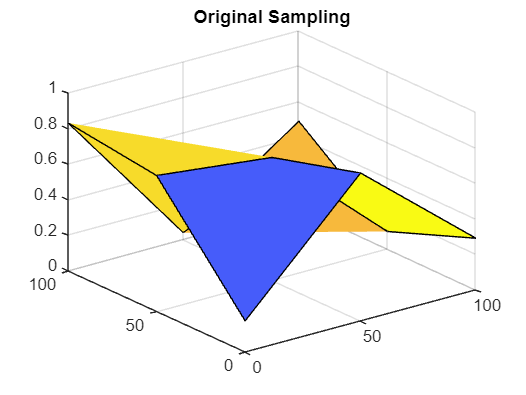

V = peaks(X,Y);

figure
surf(X,Y,result)
title('Original Sampling');


[Xq,Yq] = meshgrid(-3:0.25:3);



Vq = interp2(X,Y,reshape(result(:,3),[101,101]),Xq,Yq);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.




figure
surf(Xq,Yq,Vq);
title('Linear Interpolation Using Finer Grid');





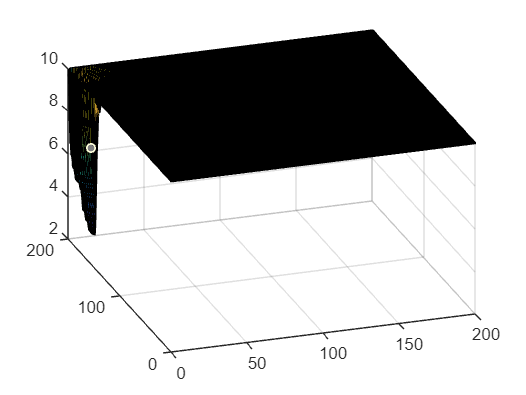

figure
j=7;
surf(bots(j).mesh_map{1},bots(j).mesh_map{2},bots(j).mesh_map{3})

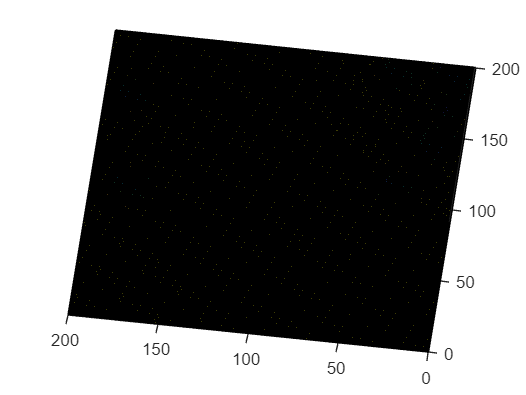

total_map =0;
for j =1:length(bots)
    total_map = total_map + bots(j).mesh_map{3};
end
figure
j=3;
surf(bots(j).mesh_map{1},bots(j).mesh_map{2},total_map)

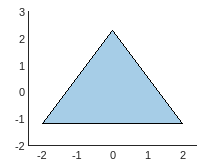

x0 = [0;0;0];
x=x0;
goal = [15;-20];
dt = 0.1;
noise = 0;
states = x;
v_hist=[];
w_hist=[];
kg=2;
kl=1;
p = nsidedpoly(3, 'Center', [0 ,0], 'SideLength', 4);
figure 
clf, hold on
plot(rotate(p,x(3),x(1:2)'))
drawnow
hold off

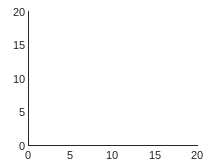


while norm(x(1:2)-goal) > 0.1
    e_k = norm(goal - x(1:2));
    th_k = atan2(goal(2)-x(2),goal(1)-x(1));
    v = kg.*cos(th_k - x(3)).*e_k;
    w = 2.*kg.*sin(th_k - x(3)).*cos(th_k - x(3)) + kl .* (2.* th_k - x(3));
    x=x + [v.*dt.*cos(x(3)+w.*dt./2);
                           v.*dt.*sin(x(3)+w.*dt./2);
                           w.*dt] + noise.*randn(3,1);
    states= [states,x];
    v_hist=[v_hist,v];
    w_hist=[w_hist,w];

    clf, hold on
    xlim([0 20])
    ylim([0 20])
    p = nsidedpoly(3, 'Center', x(1:2)', 'SideLength', 1);
    plot(rotate(p,x(3),x(1:2)'))
    drawnow
    pause(0.5);
    hold off
    


end

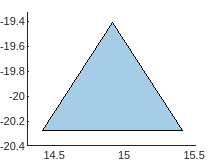

plot(p)

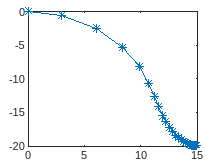

figure
plot(states(1,:),states(2,:),'Marker','*')

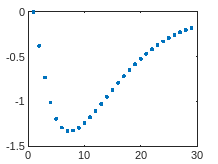

figure
plot(states(3,:),'.')

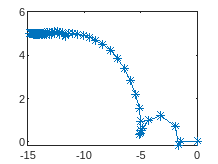

x0 = [0;0;0];
x=x0;
goal = [-15;5];
dt = 0.1;
noise = 0;
states = x;
v_hist=[];
w_hist=[];

while norm(x(1:2)-goal) > 0.1
    e_k = norm(goal - x(1:2));
    th_k = atan2(goal(2)-x(2),goal(1)-x(1));
    v = 0.5*2.*cos(th_k - x(3)).*e_k;
    w = 0.5*4.*sin(th_k - x(3)).*cos(th_k - x(3)) + 2 .* (2.* th_k - x(3));
    x=x + dt.* [ cos(x(3)).*(v);
                                    sin(x(3)).*(v);
                                    w ]+noise.*randn(3,1);
    states= [states,x];
    v_hist=[v_hist,v];
    w_hist=[w_hist,w];

end
figure
plot(states(1,:),states(2,:),'Marker','*')

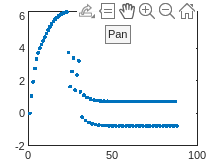

figure
plot(states(3,:),'.')

function [c,ceq] =constr(x)
    c =x*x' - 1
    ceq=[]
end

